Textfile = load("STM32Output.txt")

Textfile =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


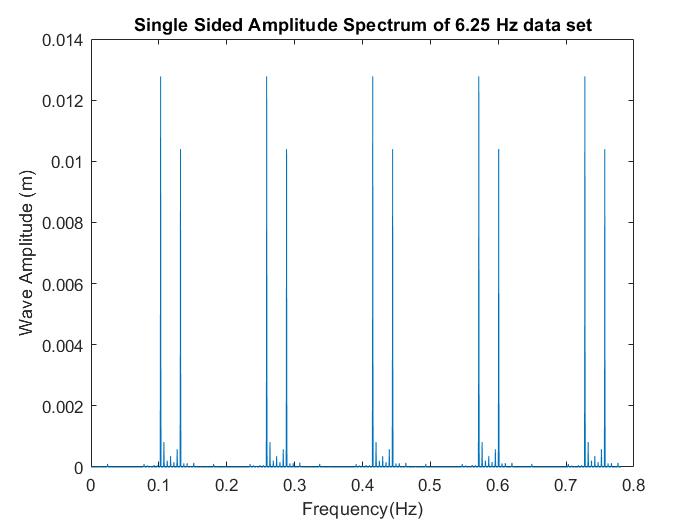

writematrix(Textfile, "STM32Output.csv");
FFTData = readtable("STM32Output.csv");


N =  10240 - 1; 
FFTData = FFTData{:, 1}/N; %data is symmetric, *2 to account for contribution of other half 
fs = 6.25/2;
frequency = fs*(0:(N/2))/N;

plot(frequency(1:2560), FFTData(1:2560)); %only plotting the real side of the dataset 
title("Single Sided Amplitude Spectrum of 6.25 Hz data set");
xlabel("Frequency(Hz)");
ylabel("Wave Amplitude (m)");